**Laborator 10 - Integrare numerică**

t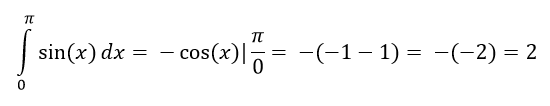

P1

int = integral(@sin, 0, pi);

disp(int);

    2.0000




trapez = Trapez(@sin, 0, pi, 100);
disp(trapez);

    1.9988



simpson = Simpson(@sin, 0, pi, 100);
disp(simpson);

    1.9990



dreptunghi = Dreptunghi(@sin, 0, pi, 100);
disp(dreptunghi);

    1.9996




trapez2 = Trapez(@sin, 0, pi, 1000);
disp(trapez2);

    2.0000



simpson2 = Simpson(@sin, 0, pi, 1000);
disp(simpson2);

    2.0000



dreptunghi2 = Dreptunghi(@sin, 0, pi, 1000);
disp(dreptunghi2);

    2.0000



P3.

a = 1; 
b = 2;
f = @(x) 1/x;
e = 0.00001;

disp("Rezultatul metodei de cuadratura adaptiva pentru ")

Rezultatul metodei de cuadratura adaptiva pentru 


disp("-----------------------");

-----------------------


disp("metoda trapezului");

metoda trapezului


t = cuadraturaAdaptivaT(f,a,b,e)

t = 0.6937

disp(t);

    0.6937



disp("-----------------------");

-----------------------


disp("metodat dreptunghiului");

metodat dreptunghiului


d = cuadraturaAdaptivaD(f,a,b,e)

d = 0.6238

disp(d);

    0.6238



disp("-----------------------");

-----------------------


disp("metoda lui Simpson");

metoda lui Simpson


s = cuadraturaAdaptivaS(f,a,b,e)

s = 0.6931

disp(s);

    0.6931



**P4. Implementați metoda lui Romberg.**

% Aproximăm integrala funcției sin(x) pentru intervalul [0, pi]:
f = @(x)sin(x);
a = 0;
b = pi;
fprintf("Romberg:");

Romberg:

fprintf("Valoarea integralei date este: %7.2f", Romberg(f, a, b));

Valoarea integralei date este:    2.00

P5. Implementați adquad.

% Folosim aceeași integrală, de mai sus.
f = @(x)sin(x);
a = 0;
b = pi;
fprintf("Adquad:");

Adquad:

fprintf("Valoarea integralei date este: %7.2f", adquad(f, a, b, 1E-3, @Romberg));

Valoarea integralei date este:    2.00

fprintf("Adquad II:");

Adquad II:

fprintf("Valoarea integralei date este: %7.2f", adquad2(f, a, b, 1E-3));

Valoarea integralei date este:    2.00

P1. Practic

f = @(x) x.^2;
a = 0;
b = 1;
n = 3;

integral_value = NewtonCotesClosedFormula(f, a, b, n);
disp("Generat ̧i formule Newton-Cotesˆınchise pentru un num ̆ar denoduri dat.");

Generat ̧i formule Newton-Cotesˆınchise pentru un num ̆ar denoduri dat.


disp("n=3")

n=3


disp(integral_value);

    0.8889



P2.

f=@(x) exp(x.^2);

rez_integral = integral(f,0,1);
disp(rez_integral);

    1.4627



rez_quad = quad(f, 0, 1, 0.0001);
disp(rez_quad);

    1.4627




rez_cuad_drept = cuadraturaAdaptivaD(f,0,1,0.0001);
disp(rez_cuad_drept);

    1.3164



rez_cuad_trapez = cuadraturaAdaptivaT(f,0,1,0.0001);
disp(rez_cuad_trapez);

    1.4596



rez_cuad_simpson = cuadraturaAdaptivaS(f,0,1,0.0001);
disp(rez_cuad_simpson);

    1.4626



rez_dreptunghi_repetat = Dreptunghi(f, 0, 1, 5);
disp(rez_dreptunghi_repetat);

    1.0041



rez_trapez_repetat = Trapez(f, 0, 1, 5);
disp(rez_trapez_repetat);

    1.3014



rez_simpson_repetat = Simpson(f, 0, 1, 5);
disp(rez_simpson_repetat);

    0.9663



rez_adquad = adquad2(f, 0, 1, 0.0001);
disp(rez_adquad);

    1.4627



rez_newton_cotes = NewtonCotesClosedFormula(f, 0, 1, 5);
disp(rez_newton_cotes);

   84.2572

